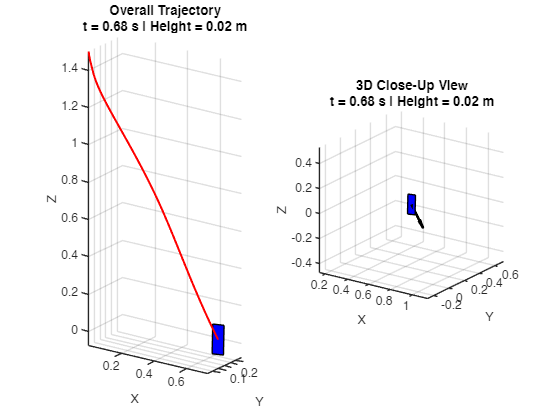

Hit ground at t = 0.69 s


% 3D Falling Paper Simulation with 3D Close-Up View,
% Live Trajectory, Paper Orientation, Black Velocity Arrow,
% and Data Export to Excel with Additional Aerodynamic Quantities
clear; clc; close all;

%% Paper Parameters
width = 0.2;       % x-dimension (m)
height = 0.15;     % y-dimension (m)
thickness = 0.001; % z-dimension (m) (thin sheet)
mass = 0.01;       % (kg)
rho_air = 1.225;   % air density (kg/m^3)
g = 9.81;          % gravitational acceleration (m/s^2)
Cd = 1.2;          % drag coefficient
Cl = 0.8;          % lift coefficient
wind_velocity = [1.5; 0; 0];  % Wind in x-direction (m/s)

% Inertia tensor (for a thin rectangular sheet)
I = diag([(1/12)*mass*(height^2 + thickness^2), ...
          (1/12)*mass*(width^2 + thickness^2), ...
          (1/12)*mass*(width^2 + height^2)]);

%% Initial Conditions
pos = [0; 0; 1.5];
vel = [0; 0; 0];
eul = deg2rad([20; 10; 0]);  % Euler angles [yaw; pitch; roll]
omega = [2; 2; 2];

%% Simulation Settings
dt = 0.01;
T = 5;
N = floor(T/dt);

%% Data Logging: 
% Columns: 1:time, 2-4: pos, 5-7: vel, 8-10: Euler angles, 11-13: omega, 
% 14-16: angular momentum L, 17: A_proj, 18: KE, 
% 19: Drag magnitude, 20: Lift magnitude, 21: Reynolds number.
data = zeros(N, 21);

% Function to convert Euler angles to rotation matrix (ZYX convention)
rotm = @(eul) eul2rotm(eul);

%% Define Paper Corners (local coordinates)
corners = 0.5 * [ -width  width  width -width;
                  -height -height height height;
                   0      0     0      0];

%% Setup Figure with Two 3D Subplots

figure;

% Left subplot: Overall view with trajectory
ax1 = subplot(1,2,1);
hold(ax1, 'on');
hPaper1 = patch('Parent', ax1, 'Vertices', zeros(4,3), 'Faces', [1 2 3 4], 'FaceColor', 'b');
hTrajectory = line('Parent', ax1, 'XData', [], 'YData', [], 'ZData', [], ...
    'Color', 'r', 'LineWidth', 1.5);
axis(ax1, [-6 6 -6 6 0 6]);
xlabel(ax1, 'X'); ylabel(ax1, 'Y'); zlabel(ax1, 'Z');
title(ax1, 'Overall Trajectory');
view(ax1, 35, 20);
grid(ax1, 'on');
axis(ax1, 'equal');

% Right subplot: 3D Close-Up View with paper orientation and velocity arrow
ax2 = subplot(1,2,2);
hold(ax2, 'on');
hPaper2 = patch('Parent', ax2, 'Vertices', zeros(4,3), 'Faces', [1 2 3 4], 'FaceColor', 'b');
% Create an initial velocity arrow (quiver3) with black color ('k')
scale_v = 0.05;  % scale factor for velocity arrow length
hVel = quiver3(ax2, pos(1), pos(2), pos(3), scale_v*vel(1), scale_v*vel(2), scale_v*vel(3), ...
    'k', 'LineWidth', 2, 'MaxHeadSize', 2);
axis(ax2, 'equal');
xlabel(ax2, 'X'); ylabel(ax2, 'Y'); zlabel(ax2, 'Z');
title(ax2, '3D Close-Up View');
grid(ax2, 'on');
view(ax2, 35, 20);

%% Preallocate arrays for trajectory plotting
traj_x = [];
traj_y = [];
traj_z = [];

% Dynamic viscosity for air (Pa·s)
mu = 1.81e-5;

%% Simulation Loop
for i = 1:N
    t = (i-1)*dt;
    
    % Compute rotation matrix from Euler angles
    R = rotm(eul);
    
    % Relative velocity with respect to wind
    v_rel = vel - wind_velocity;
    v_mag = norm(v_rel) + 1e-6;
    
    % Paper’s normal (z-axis in body frame)
    n = R(:,3);
    
    % Compute projected area for drag force
    A_proj = width * height * abs(dot(n, v_rel/v_mag));
    Fd = -0.5 * rho_air * Cd * A_proj * v_mag * v_rel;
    
    % Compute lift force (perpendicular to both the paper's normal and relative velocity)
    lift_dir = cross(cross(v_rel, n), v_rel);
    lift_dir = lift_dir / (norm(lift_dir) + 1e-6);
    Fl = 0.5 * rho_air * Cl * A_proj * v_mag^2 * lift_dir;
    
    % Buoyancy force (small effect)
    V = width * height * thickness;
    Fb = [0; 0; rho_air * V * g];
    
    % Gravity force
    Fg = [0; 0; -mass * g];
    
    % Net force and acceleration
    F_net = Fd + Fl + Fb + Fg;
    acc = F_net / mass;
    
    % Compute torque (apply lift force at a small offset along the paper's z-axis)
    r_lift = R * [0; 0; 0.001];
    torque = cross(r_lift, Fl);
    
    % Angular acceleration (using Euler’s rotation equations)
    alpha = I \ (torque - cross(omega, I * omega));
    
    % Update linear motion: velocity and position
    vel = vel + acc * dt;
    pos = pos + vel * dt;
    
    % Update angular motion: Euler angles and angular velocity
    omega = omega + alpha * dt;
    eul = eul + omega * dt;
    
    % Angular momentum and kinetic energy
    L = I * omega;
    KE = 0.5 * mass * norm(vel)^2 + 0.5 * omega' * I * omega;
    
    % Additional quantities: Drag force magnitude, Lift force magnitude, and Reynolds number.
    Fd_mag = norm(Fd);
    Fl_mag = norm(Fl);
    Re = (rho_air * v_mag * width) / mu;
    
    % Log simulation data (ensure final value is saved)
    data(i,:) = [t, pos(:)', vel(:)', eul(:)', omega(:)', L(:)', A_proj, KE, Fd_mag, Fl_mag, Re];
    
    % Stop simulation if paper hits the ground (z <= 0)
    if pos(3) <= 0
        fprintf('Hit ground at t = %.2f s\n', t);
        break;
    end
    
    %% Update Trajectory for Overall View
    traj_x(end+1) = pos(1);
    traj_y(end+1) = pos(2);
    traj_z(end+1) = pos(3);
    
    %% Transform Paper Corners to World Coordinates
    transformed = (R * corners) + pos;
    
    %% Update Overall View (ax1)
    set(hPaper1, 'Vertices', transformed');
    set(hTrajectory, 'XData', traj_x, 'YData', traj_y, 'ZData', traj_z);
    title(ax1, sprintf('Overall Trajectory\nt = %.2f s | Height = %.2f m', t, pos(3)));
    
    %% Update 3D Close-Up View (ax2)
    set(hPaper2, 'Vertices', transformed');
    % Adjust the close-up view to center on the current paper position (with a margin)
    margin = 0.5;
    axis(ax2, [pos(1)-margin pos(1)+margin, pos(2)-margin pos(2)+margin, pos(3)-margin pos(3)+margin]);
    title(ax2, sprintf('3D Close-Up View\nt = %.2f s | Height = %.2f m', t, pos(3)));
    
    % Update the black velocity arrow in the close-up view using the actual velocity
    set(hVel, 'XData', pos(1), 'YData', pos(2), 'ZData', pos(3), ...
        'UData', scale_v * vel(1), 'VData', scale_v * vel(2), 'WData', scale_v * vel(3));
    
    drawnow;
    pause(0.01);
end

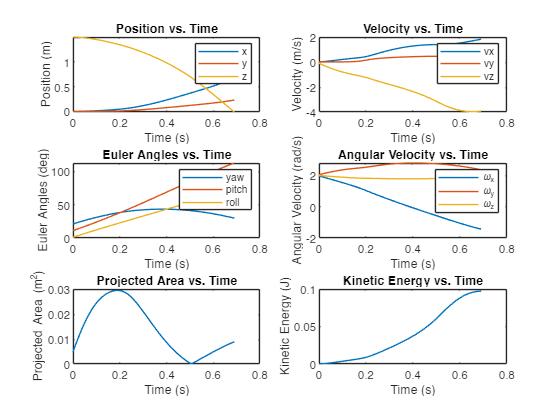


%% Trim Log Data to Actual Simulation Steps (include final step)
data = data(1:i,:);

%% Generate Graphs After Simulation

time = data(:,1);

figure;
subplot(3,2,1);
plot(time, data(:,2:4));
legend('x','y','z');
ylabel('Position (m)');
xlabel('Time (s)');
title('Position vs. Time');

subplot(3,2,2);
plot(time, data(:,5:7));
legend('vx','vy','vz');
ylabel('Velocity (m/s)');
xlabel('Time (s)');
title('Velocity vs. Time');

subplot(3,2,3);
plot(time, rad2deg(data(:,8:10)));
legend('yaw','pitch','roll');
ylabel('Euler Angles (deg)');
xlabel('Time (s)');
title('Euler Angles vs. Time');

subplot(3,2,4);
plot(time, data(:,11:13));
legend('\omega_x','\omega_y','\omega_z');
ylabel('Angular Velocity (rad/s)');
xlabel('Time (s)');
title('Angular Velocity vs. Time');

subplot(3,2,5);
plot(time, data(:,17));
ylabel('Projected Area (m^2)');
xlabel('Time (s)');
title('Projected Area vs. Time');

subplot(3,2,6);
plot(time, data(:,18));
ylabel('Kinetic Energy (J)');
xlabel('Time (s)');
title('Kinetic Energy vs. Time');

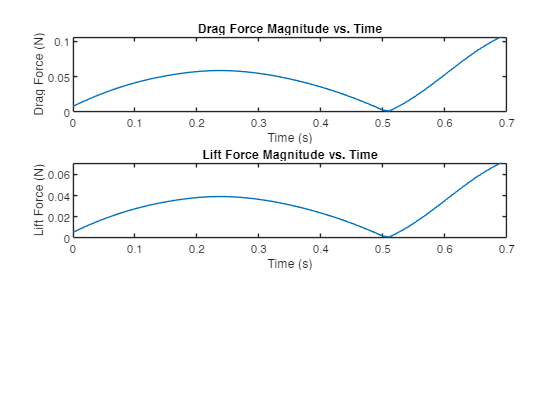


figure;
subplot(3,1,1);
plot(time, data(:,19));
ylabel('Drag Force (N)');
xlabel('Time (s)');
title('Drag Force Magnitude vs. Time');

subplot(3,1,2);
plot(time, data(:,20));
ylabel('Lift Force (N)');
xlabel('Time (s)');
title('Lift Force Magnitude vs. Time');

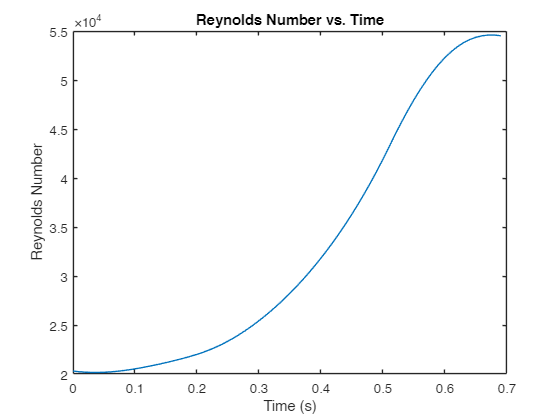


figure;
plot(time, data(:,21));
ylabel('Reynolds Number');
xlabel('Time (s)');
title('Reynolds Number vs. Time');


%% Write Data to Excel
% Downsample data at 0.1 second intervals (ensuring final sample is included)
sample_interval = 0.1;
sample_step = round(sample_interval/dt);
indices = 1:sample_step:size(data,1);
if indices(end) ~= size(data,1)
    indices = [indices, size(data,1)];  % Horizontal concatenation, not vertical
end
data_downsampled = data(indices, :);

% Create a table with appropriate variable names and descriptions.
T_table = array2table(data_downsampled, 'VariableNames', ...
    {'Time','PosX','PosY','PosZ','VelX','VelY','VelZ',...
     'Euler_yaw','Euler_pitch','Euler_roll',...
     'Omega_x','Omega_y','Omega_z',...
     'L_x','L_y','L_z',...
     'A_proj','KE','Drag','Lift','Reynolds'});

% Write the table to an Excel file.
fileName = fullfile(pwd, 'FallingPaperData.xlsx');
disp(['Saving Excel file to: ', fileName]);

Saving Excel file to: C:\Users\Krunal\Documents\MATLAB\FallingPaperData.xlsx


try
    writetable(T_table, fileName);
    fprintf('Excel sheet "FallingPaperData.xlsx" generated with simulation data.\n');
catch ME
    fprintf('Error writing to Excel file: %s\n', ME.message);
end

Excel sheet "FallingPaperData.xlsx" generated with simulation data.



%% Euler to Rotation Matrix Function (ZYX Convention)
function R = eul2rotm(eul)
    % Extract individual Euler angles: yaw (psi), pitch (theta), roll (phi)
    psi = eul(1);
    theta = eul(2);
    phi = eul(3);
    
    % Construct the rotation matrix using ZYX convention
    R = [ cos(theta)*cos(psi) - sin(phi)*sin(theta)*sin(psi), -cos(phi)*sin(psi), sin(theta)*cos(psi) + sin(phi)*cos(theta)*sin(psi);
          cos(theta)*sin(psi) + sin(phi)*sin(theta)*cos(psi),  cos(phi)*cos(psi), sin(theta)*sin(psi) - sin(phi)*cos(theta)*cos(psi);
         -cos(phi)*sin(theta), sin(phi), cos(phi)*cos(theta) ];
end
